## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "bids-matlab-tools" v6.0 (see >> help eegplugin_bids) - new version 6.1 available
EEGLAB: adding "clean_rawdata" v2.5 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)


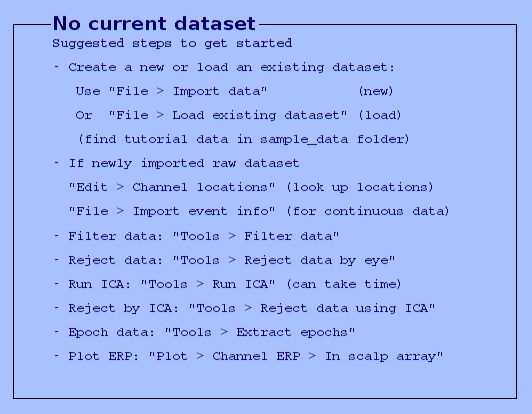

You are using the latest version of EEGLAB.


eeglab

**Steps:**

Select the BIDS folder to work on

BIDS_path = uigetdir(pwd,'Select BIDS dataset folder')

BIDS_path = '/home/user1/Documents/Manisha/eeglab/BIDS/ds003061'

Add the folder and subfolders to path. Make the selected BIDS folder to current directory.

addpath(genpath(BIDS_path))

current_path = pwd;
if strcmp(current_path,BIDS_path)==0
    disp('Changing current directory to BIDS dataset folder')
    cd(BIDS_path)
end
[~,dataset_name,~] = fileparts(BIDS_path) 

dataset_name = 'ds003061'

**Test whether the BIDS dataset has a participants.tsv and whether it is empty**

if ~isfile('participants.tsv')
    error('Cannot find participants.tsv')
end

d = dir;
% if a directory is empty, it will contain only '.' and '..'
if (isfolder(BIDS_path)==0) || (length(d)==2) 
    error(['Cannot find ' dataset_name ' BIDS dataset, download it from OpenNeuro.org, uncompress it'])
end

if ~isfolder(fullfile([BIDS_path, '/sub-001/eeg']))
    error(['Cannot find subject and eeg subfolder in the BIDS dataset, download it from OpenNeuro.org, uncompress it'])
    
end

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG] = pop_importbids(BIDS_path,'bidsevent','off','bidschanloc','off','studyName',dataset_name);

Importing file: /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-1_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-1_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importing file: /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-2_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-2_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importing file: /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-3_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/BIDS/ds003061/sub-001/eeg/sub-001_task-P300_run-3_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importi

**Check whether an events.json file exists or not. Epoch generation will depend on this.**

filePattern = fullfile(BIDS_path, '*_events.json'); 

json_files = dir(filePattern);
if isempty(json_files)
    disp('No events file detected. Regular 2s epochs will be generated')
    event_file = 0;
else
    disp('Events file detected! Epochs will be generated with [-0.5, 1.5]s time window ')
    event_file = 1;
end

Events file detected! Epochs will be generated with [-0.5, 1.5]s time window 


## Process dataset

Loop across datasets and process data epochs. The type of epoch and any other interesting field is in epoch_type.datasetinfo.trialinfo; all fields in this structure will be saved as different columns. Pass a label filename which will be updated by mat2tiff_EEG.

aws_path = ['s3://openneuro.org/' dataset_name];
label_file = [dataset_name '_labels_s3.txt'];

CURRENTSTUDY = 1;
for CURRENTSET = 1:length(ALLEEG)
    CURRENTSET
    EEG =  ALLEEG(CURRENTSET);
    if event_file == 1
        EEG = pop_epoch(EEG, unique({EEG.event.type}), [-0.5 1.5]);
    else
        EEG = eeg_regepochs(EEG, 'limits', [0 2], 'recurrence', 2);
    end
    mat2sample_extendedLabel_EEG(EEG,label_file,aws_path)
end

CURRENTSET = 1

pop_epoch():863 epochs selected
Epoching...
pop_epoch():862 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-001/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 2

pop_epoch():862 epochs selected
Epoching...
pop_epoch():860 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-001/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 3

pop_epoch():860 epochs selected
Epoching...
pop_epoch():858 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-001/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 4

pop_epoch():812 epochs selected
Epoching...
pop_epoch():810 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-002/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 5

pop_epoch():807 epochs selected
Epoching...
pop_epoch():806 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-002/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 6

pop_epoch():799 epochs selected
Epoching...
pop_epoch():798 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-002/eeg'

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
